# 360全景透视与环形鱼眼图像顺滑过渡算法

author:崔星星

date:2024.9

## 问题描述

为了在本APP中较顺滑的在“透视”和”环形鱼眼“两种视角平滑过渡渲染，数学上表现为单位球体内，外之间视角变换，不能简单的对各个变量进行线性插值(仅适用球体内的”小行星“和”透视“之间的模式)，我特意画出如下示意图：

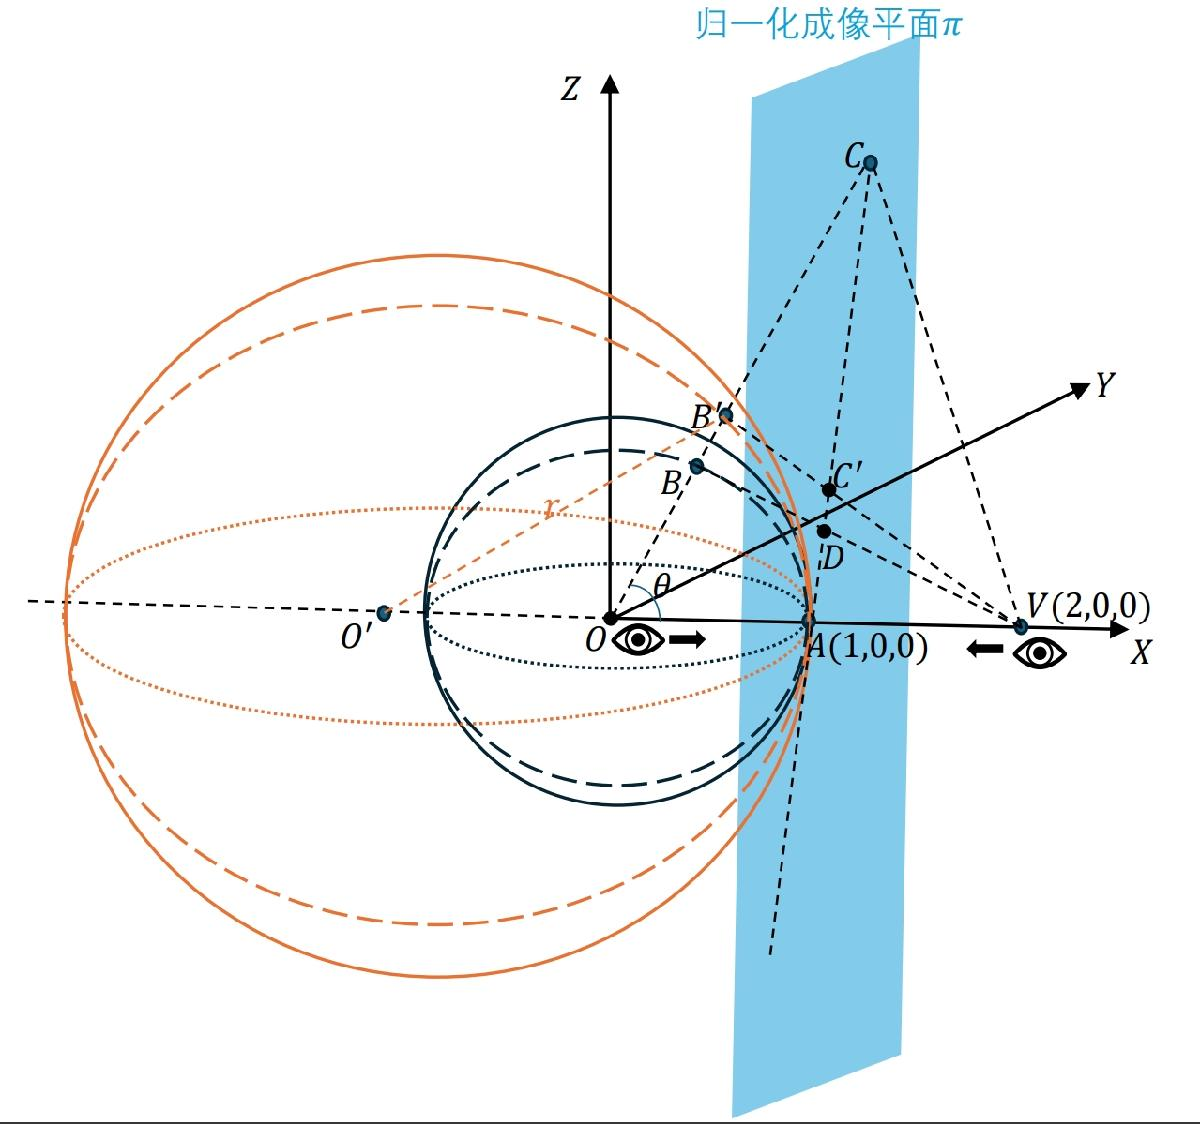

两种视角模式：

- 从球心$O\left(0,0,0\right)$向目标点$A\left(1,0,0\right)$方向观看，黑色的单位球面纹理在归一化成像平面$\pi$上的投影为透视无畸变投影（[Gnomonic projection](https://en.wikipedia.org/wiki/Gnomonic_projection)）

- 从点$V\left(2,0,0\right)$向目标点$A\left(1,0,0\right)$方向观看，黑色的单位球面纹理在归一化成像平面$\pi$上的投影为鱼眼投影（[Fisheye Projection](https://wiki.panotools.org/Fisheye_Projection)）

要在上述两种模式之间使得观察图像平滑过渡，那么每个投影像素点坐标要连续变化，即不能突变，表现在投影成像平面$\pi$上的无畸变点$C$(从点$O$看，点$B$在平面$\pi$上的投影点)和畸变点$D$(从点$V$看，点$B$在平面$\pi$上的投影点)之间的顺滑过渡。橙色大球体是一个半径$r\in \left\lbrack 1,\inf \right\rbrack$范围，球心$O^{\prime }$位于$X$负半轴，并且始终与点$A$相切不断变化的球体。黑色小球体是一个半径为1，位置始终固定的单位球体，其表面纹理为一副360° [equirectangular类型](https://en.wikipedia.org/wiki/Equirectangular_projection)全景渲染图像，点$B$为单位球体纹理表面上任意一点，在点$O$沿着视线方向看，即延长$\textrm{OB}$与橙色大球体表面相交于点$B^{\prime }$,与平面$\pi$相交于点$C$，连接点$B^{\prime }$和点$V$，与平面$\pi$相交于点$C^{\prime }$，当橙色大球体半径逐渐变动时，那么点$C^{\prime }$即为过渡变化点。由简单的几何关系可知，点$C$,$C^{\prime }$,$D$,$A$四点始终共线。

相应地，**单位球体上弧**$\hat{\textrm{AB}}$**的纹理映射到橙色大球体上弧**$\hat{A{\mathrm{B}}^{\prime } }$**,这样从点**$V$**看，实际点**$B$**在平面**$\pi$**上的投影点看起来像是从虚拟点**${\mathrm{B}}^{\prime }$**投影到点**$C^{\prime }$**产生的，从而达到了图像像素点顺滑过渡的效果！**

## 问题求解

现问题变为：已知点$B$坐标为$\left(x_0 ,y_0 ,z_0 \right)$,摄像机视场角为$\theta$，即图中$\angle \textrm{COV}=\theta$，$\|O^{\prime } B^{\prime } \parallel =r$，求虚拟点$B^{\prime }$的坐标$\left(x,y,z\right)$。

在$\bigtriangleup O^{\prime } \textrm{OB}$中，设$\|OB^{\prime } \parallel =l$,利用三角形余弦公式，可知：


$$r^2 ={\left(r-1\right)}^2 +l^2 -2l\left(r-1\right)\cos \left(\pi -\theta \right)$$


可求解$l$(两个解，取较小者)，然后利用等比关系，进而可求解得到点$B^{\prime }$的坐标如下：


$$\left\lbrace \begin{array}{ll}
x= & l*\cos \left(\theta \right)\\
y= & \frac{y_0 *l*\cos \left(\theta \right)}{x_0 }\\
z= & \frac{z_0 *l*\cos \left(\theta \right)}{x_0 }
\end{array}\right.$$


程序计算：

syms r l theta
equ = r.^2==(r-1).^2+l.^2-2*l*(r-1).*cos(pi-theta)

$$equ = r^{2}={\left(r-1\right)}^{2}+l^{2}+2\,l\,\cos\left(\theta \right)\,\left(r-1\right)$$


sol = solve(equ,l)

$$sol = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta \right)+\sigma_{1}-r\,\cos\left(\theta \right)\\ \cos\left(\theta \right)-\sigma_{1}-r\,\cos\left(\theta \right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r^{2}\,{\cos\left(\theta \right)}^{2}-2\,r\,{\cos\left(\theta \right)}^{2}+2\,r+{\cos\left(\theta \right)}^{2}-1} \end{array}$$

从求解的结果sol看出有2个解，取较小者第2个解：

l = sol(2)

$$l = \cos\left(\theta \right)-\sqrt{r^{2}\,{\cos\left(\theta \right)}^{2}-2\,r\,{\cos\left(\theta \right)}^{2}+2\,r+{\cos\left(\theta \right)}^{2}-1}-r\,\cos\left(\theta \right)$$

带入最终公式，得到点$B^{\prime }$的坐标$\left(x,y,z\right)$如下：

syms x_0 y_0 z_0
x = l*cos(theta)

$$x = -\cos\left(\theta \right)\,\left(\sqrt{r^{2}\,{\cos\left(\theta \right)}^{2}-2\,r\,{\cos\left(\theta \right)}^{2}+2\,r+{\cos\left(\theta \right)}^{2}-1}-\cos\left(\theta \right)+r\,\cos\left(\theta \right)\right)$$

y = y_0*x/x_0

$$y = -\frac{y_{0}\,\cos\left(\theta \right)\,\left(\sqrt{r^{2}\,{\cos\left(\theta \right)}^{2}-2\,r\,{\cos\left(\theta \right)}^{2}+2\,r+{\cos\left(\theta \right)}^{2}-1}-\cos\left(\theta \right)+r\,\cos\left(\theta \right)\right)}{x_{0}}$$

z = z_0*x/x_0

$$z = -\frac{z_{0}\,\cos\left(\theta \right)\,\left(\sqrt{r^{2}\,{\cos\left(\theta \right)}^{2}-2\,r\,{\cos\left(\theta \right)}^{2}+2\,r+{\cos\left(\theta \right)}^{2}-1}-\cos\left(\theta \right)+r\,\cos\left(\theta \right)\right)}{x_{0}}$$